# Simple script to generate DLV model data


clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of “neurons” (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
param.tau_F = [0.3 1 3 10]; % Time constants (in seconds) for each OU field
%ones(1, param.N_F); % controls the time constants of the latents
param.T = 100; % Total simulation time (in seconds)

% ordered_J_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F);
% ordered_J_if(1:64, 2:4) = 0;
% ordered_J_if(65:128, [1 3 4]) = 0;
% ordered_J_if(129:192, [1 2 4]) = 0;
% ordered_J_if(193:end, [1 2 3]) = 0;

param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 1*param.eta_val; % 2.67 previous, "Inverse temperature" and silence bias

[s_i, param, h_f] = sampleMorrellModel(param);

## **Visualizing the Raw data and the latent variables**

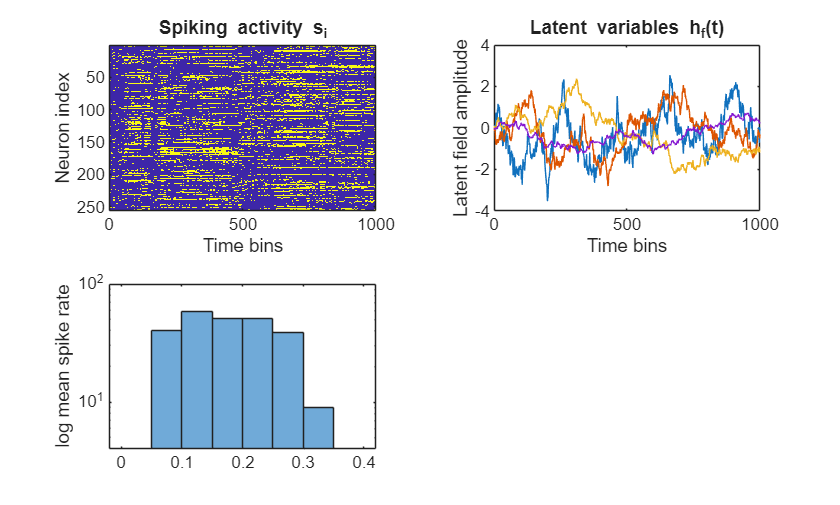

% s_centered = double(s_i) - mean(s_i,2);

figure()
nexttile
imagesc(s_i)
xlabel('Time bins')
ylabel('Neuron index')
xlim([0 1000]);
title('Spiking activity s_i')

nexttile
plot(h_f)
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
nexttile
histogram(mean(s_i,2));
set(gca, 'YScale', 'log'); 
ylabel('log mean spike rate');

## looking at PCA and relationship to ground truth (h_f, J_if)

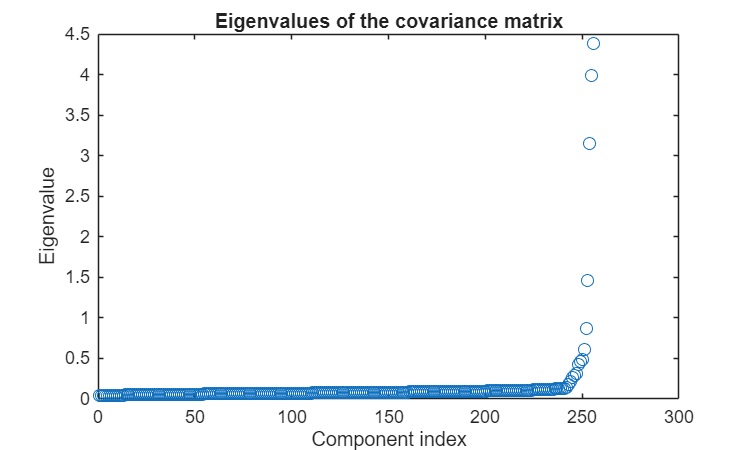

% getting the eigenvalues of covariance matrix
eig_vals = eig(cov(s_i'));
figure('Position',[100 100 500 300]) 
plot(eig_vals, 'o')
xlabel('Component index')
ylabel('Eigenvalue')
title('Eigenvalues of the covariance matrix')

warning('off', 'MATLAB:rankDeficientMatrix')
s_i_double = double(s_i);

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(s_i_double');

% Find how many PCs are needed to explain 85% variance
cum_explained = cumsum(EXPLAINED);
num_pcs_85percent = find(cum_explained >= 85, 1, 'first');
num_comp = num_pcs_85percent +20;
% Marchenko–Pastur threshold
[N, T] = size(s_i);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 13 PCs


num_com_to_plot = 10;
time_points = linspace(1,param.T,1000);

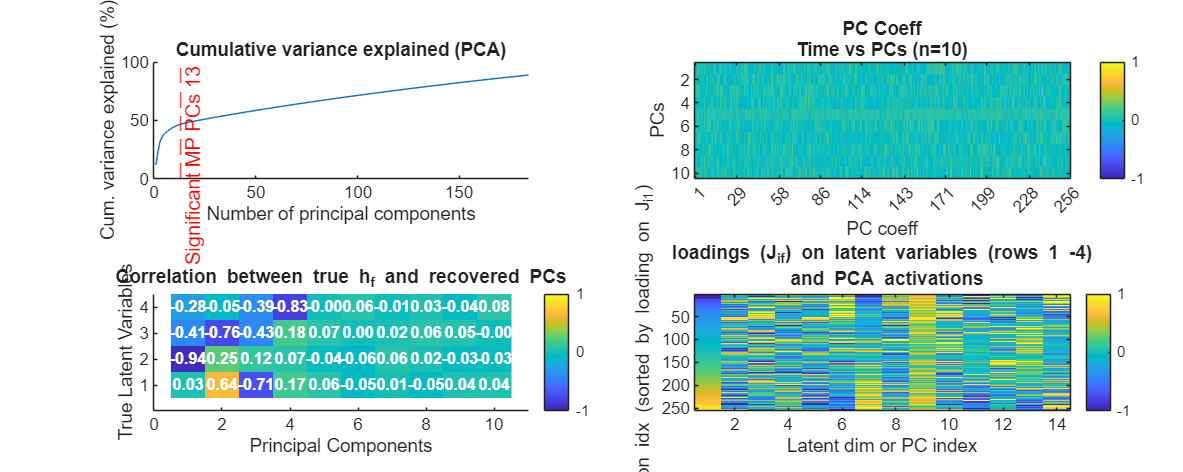

figure('Position', [100 100 2000 800]) 
nexttile
hold on;
plot(cum_explained)
xlim([0 num_comp]);
ylim([0 100]);
xline(num_sig_components,'--r', ['Significant MP PCs ' num2str(num_sig_components)]);
xlabel('Number of principal components')
ylabel('Cum. variance explained (%)')
title('Cumulative variance explained (PCA)')

nexttile
imagesc(COEFF(:,1:num_com_to_plot)', [-1 1]);
title({'PC Coeff'; ['Time vs PCs (n=' num2str(num_com_to_plot) ')']});
xlabel('PC coeff'); ylabel('PCs'); colorbar;
xlim([0 size(COEFF,1)]);
num_t_ticks = 10;
t_tick_idx = round(linspace(1, size(COEFF,1), num_t_ticks));
t_tick_lbl = arrayfun(@(x) sprintf('%d', x), t_tick_idx, 'UniformOutput', false);
set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);

nexttile
% Correlation between latent fields and PCA activations
cc_mat = corrcoef([h_f(1:size(SCORE,1),:) SCORE(:, 1:num_com_to_plot)]);
cc_mat_sub = cc_mat(1:4, 5:end);
hold on;
imagesc(cc_mat_sub, [-1 1]); colorbar;
yticks(1:4);
xlim([0 num_com_to_plot+1]);
title('Correlation between true h_f and recovered PCs');
xlabel('Principal Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(cc_mat_sub,1)
    for j = 1:size(cc_mat_sub,2)
        text(j, i, sprintf('%.2f', cc_mat_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', 'FontSize',8, ...
            'FontWeight', 'bold');
    end
end
hold off;

nexttile
[~, ord1] =sort(param.fixJ_if(:, 1)); % Sorting the neurons by their true coupling to latent 1
% Showing side-by-side the true J_i,m versus the first 10 PCA oadings
% rescaled 
imagesc([param.fixJ_if(ord1, :) COEFF(ord1, 1:num_com_to_plot)*sqrt(param.N_neur/param.N_F)], [-1 1])
xlabel('Latent dim or PC index')
ylabel('Neuron idx (sorted by loading on J_{i1})')
title({['loadings (J_{if}) on latent variables (rows 1 -' num2str(param.N_F) ')']; ... 
    ' and PCA activations'}, 'interpreter', 'tex')
colorbar


% nexttile
% imagesc(cc_mat, [-1 1])
% xlabel('PCA components')
% ylabel('Latent variable index')
% title(['corr btw latent variables (rows 1-' num2str(param.N_F) ') and PCA activations'])
% colorbar

## Reconstruction Error vs. PC number

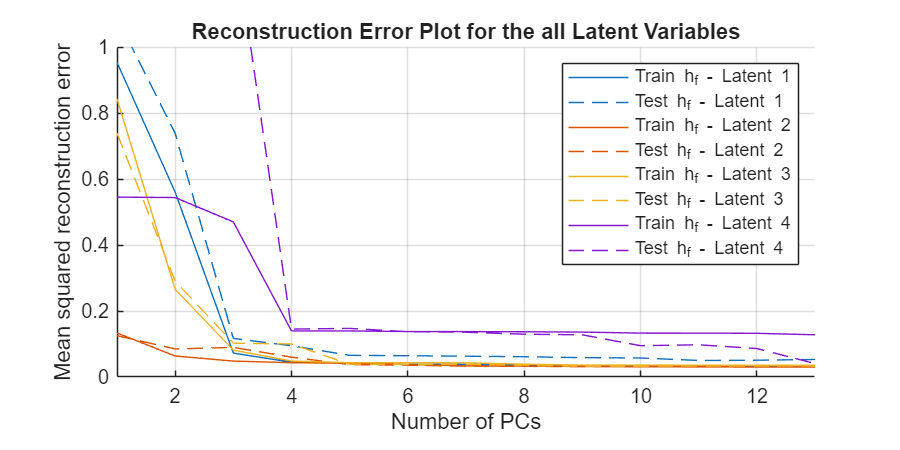

reconstruction_error = zeros(num_sig_components,param.N_F);
reconstruction_error_test = zeros(num_sig_components,param.N_F);
[s_i_test, param_test, h_f_test] = sampleMorrellModel(param);
s_i_test_double = double(s_i_test);
SCORE_test = s_i_test_double' * COEFF; 

for idx = 1:num_sig_components
    err_train = 0;
    err_test = 0;
    for f = 1:param.N_F % calculating the Recon. Error for all 4 latents
        % Expressing each latent field as a linear combinatino of PCA time
        % course with least-square method
        x_train = lsqlin(SCORE(:, 1:idx), h_f(:,f));
        h_f_reconstructed = SCORE(:, 1:idx) * x_train;
        reconstruction_error(idx,f) = mean((h_f(:,f) - h_f_reconstructed).^2);

        h_f_test_reconstructed = SCORE_test(:, 1:idx) * x_train;
        reconstruction_error_test(idx,f) = mean((h_f_test(:,f) - h_f_test_reconstructed).^2);
    end
     
end

figure(Position=[100,100, 600, 300])
nexttile
hold on;
h_f_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(1:num_sig_components, reconstruction_error(:, f), 'Color',h_f_colors(f,:),'DisplayName', ['Train h_f - Latent ' num2str(f)]);
    plot(1:num_sig_components, reconstruction_error_test(:, f), 'LineStyle', '--', 'Color',h_f_colors(f,:),'DisplayName', ['Test h_f - Latent ' num2str(f)]);
end
xlim([1 num_sig_components]);
ylim([0 1]);
xlabel('Number of PCs');
ylabel('Mean squared reconstruction error');
legend('show');
title('Reconstruction Error Plot for the all Latent Variables');
grid on;
hold off;

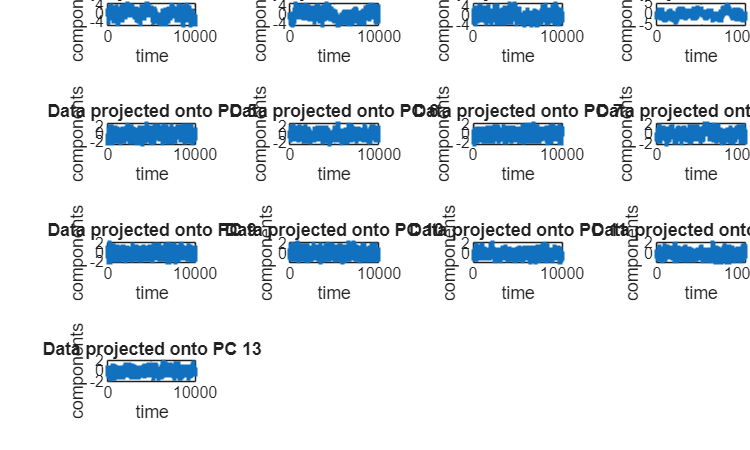


figure(Position=[100,100, 500, 300])
tiledlayout(ceil(num_sig_components/2), 2); % adjust grid size as needed

for i=1:num_sig_components
    hold on
    nexttile;
    plot(1:10000, SCORE(:, i), '.-', 'linewidth', 1) %,'Color',pc_colors(i,:)
    title(['Data projected onto PC ',num2str(i)])
    ylabel('components')
    xlabel('time')
    
end

## Simulate a "readout" of the population activity and look at the power spectrum

% neuron_locations = 1:param.N_neur;
% center_loc = 128;
% nbhd_width = 32;
% w_readout = exp(- (neuron_locations - center_loc).^2/(2*nbhd_width));
% 
% local_readout = w_readout*s_i;
% 
% figure()
% nexttile
% plot(local_readout)
% xlabel('Time bins')
% ylabel('Local readout signal')
% title('Population readout from Gaussian-weighted subset')
% 
% [psd, f_psd] = pwelch(local_readout);
% nexttile
% plot(log10(f_psd), log10(psd))
% xlabel('log_{10} Frequency (Hz)')
% ylabel('log_{10} Power spectral density')
% title('Log–log power spectrum of local readout')

## ICA Test

% PCA assumes uncorrelated Gaussian mixtures, but my latent fields are
% non-Gaussian OU processes. 

% let's assume each neuron is a channel
EEG_data = s_i_double; % ch x time

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = EEG_data;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


% Run ICA without PCA
EEG = pop_runica(EEG, 'extended', 1, 'interrupt', 'off');


Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [256,10000] = 256 channels, 10000 frames/nFinding 256 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 0 frames per ICA weight ((65536)^2 = 10000 weights, Initial learning rate will be 0.001, block size 47.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-07 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.3733 to 0.9523
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
Lowering learning rate to 0.0009 and starting again.
step 1 - lrate 0.000900, wchange 263.23765300, angledelta  0.0 deg
step 2 - lrate 0.000900, w

% The ICA activations (component time courses)
icasig = EEG.icaact;      % time course of each component, size: components × time
icasig = real(icasig);

A = EEG.icawinv;          % unmixing matrix: channels × components
W = EEG.icaweights;       % weights (unmixing) matrix

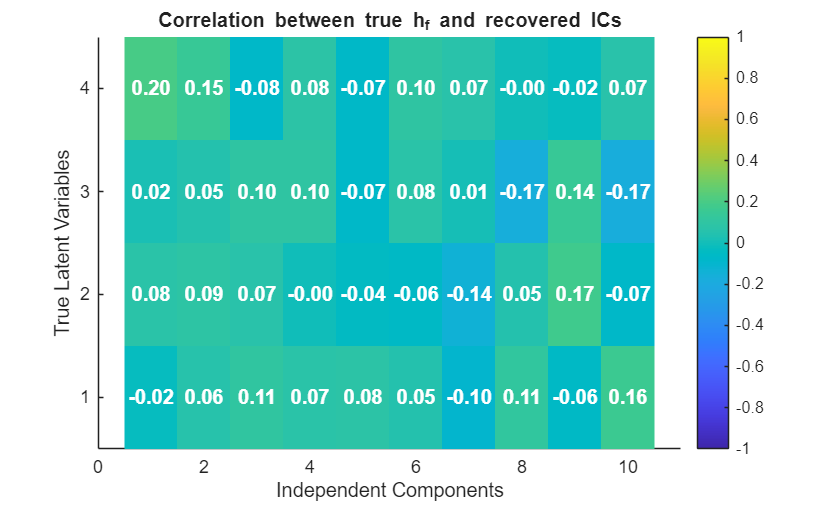

R = corrcoef([h_f, icasig']);
R_sub = R(1:4, 5:14);

figure()
hold on;
imagesc(R_sub, [-1 1]); 
colorbar;
yticks(1:4);
xlim([0 11]);
title('Correlation between true h_f and recovered ICs');
xlabel('Independent Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(R_sub,1)
    for j = 1:size(R_sub,2)
        text(j, i, sprintf('%.2f', R_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', ...
            'FontWeight', 'bold');
    end
end
hold off;

## Reconstruction Error

% Project test data into ICA space

icasig_test = EEG.icawinv' * s_i_test_double;  % size: (Neuron x IC) * Neuron X time = components × time

% Transpose to match h_f time dimension
icasig = double(EEG.icaact)';        % now time × components
icasig_test = double(icasig_test)';  % now time × components

reconstruction_error_ica = zeros(num_sig_components, param.N_F);
reconstruction_error_test_ica = zeros(num_sig_components, param.N_F);

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' ICs using least-squares
        x_train = lsqlin(icasig(:,1:idx), h_f(:,f));
        h_f_reconstructed_ica = icasig(:,1:idx) * x_train;
        reconstruction_error_ica(idx,f) = mean((h_f(:,f) - h_f_reconstructed_ica).^2);

        h_f_test_reconstructed = icasig_test(:,1:idx) * x_train;
        reconstruction_error_test_ica(idx,f) = mean((h_f_test(:,f) - h_f_test_reconstructed).^2);
    end
end

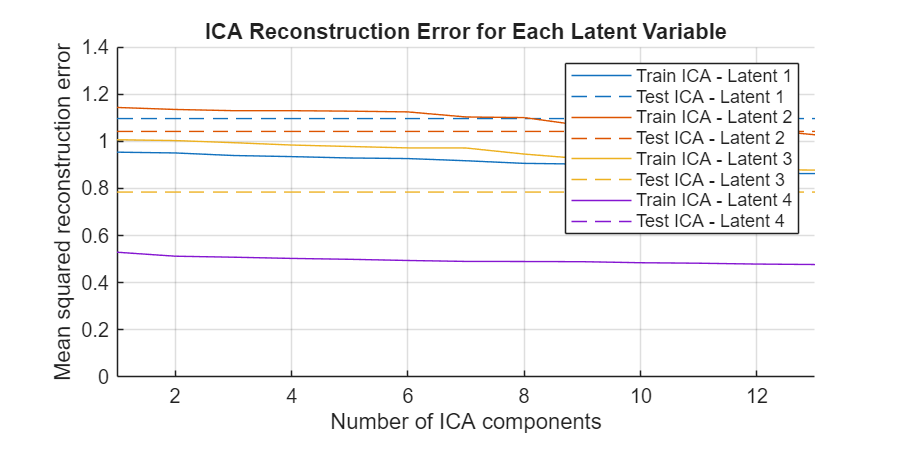


figure('Position',[100,100, 600, 300])
nexttile
hold on;
ica_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(1:num_sig_components, reconstruction_error_ica(:, f), ...
        'Color', ica_colors(f,:), 'DisplayName', ['Train ICA - Latent ' num2str(f)]);
    plot(1:num_sig_components, reconstruction_error_test_ica(:, f), ...
        'LineStyle', '--', 'Color', ica_colors(f,:), 'DisplayName', ['Test ICA - Latent ' num2str(f)]);
end

xlim([1 num_sig_components]);
ylim([0 1.4]);
xlabel('Number of ICA components');
ylabel('Mean squared reconstruction error');
legend('show');
title('ICA Reconstruction Error for Each Latent Variable');
grid on;
hold off;

## UMAP Test: Uniform Manifold Approximation and Projection

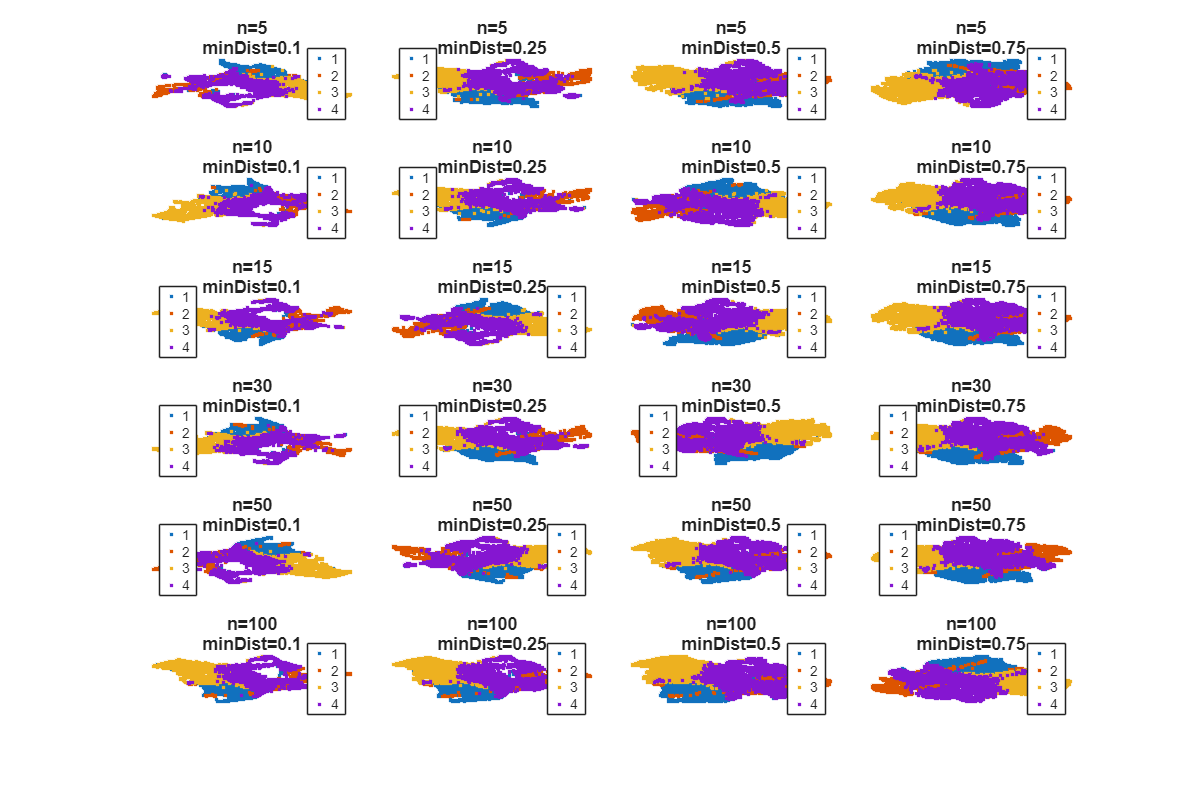

% Run UMAP
% 1.0: Testing different number of neighbors and min distances to consider

% n_neighbors_values = [15];
% min_dist_values = [0.1]; 
n_neighbors_values = [5, 10, 15, 30, 50, 100];
min_dist_values     = [0.1, 0.25, 0.5, 0.75];

figure('Position',[100,100, 1200, 800]);
tiledlayout(length(n_neighbors_values), length(min_dist_values), 'TileSpacing', 'compact');
warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');

cluster_idx = kmeans(h_f, 4);

plot_idx = 1;
for curr_n_neighbors = n_neighbors_values
    for curr_min_dist = min_dist_values
        [umap_s_i, umap_params] = run_umap(s_i_double', 'n_neighbors', curr_n_neighbors,...
            'min_dist', curr_min_dist,'n_components', 2, 'verbose', 'none', 'gui', false);

        nexttile(plot_idx)
        % scatter(umap_s_i(:,1), umap_s_i(:,2), 5, 'filled');
        gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
        title({['n=' num2str(curr_n_neighbors)], ['minDist=' num2str(curr_min_dist)]});
        axis tight; axis off;
        plot_idx = plot_idx + 1;
    end
end

[umap_s_i, umap_params] = run_umap(s_i_double', 'n_neighbors', 75,...
            'min_dist', 0.75,'n_components', 2, 'verbose', 'none', 'gui', false);

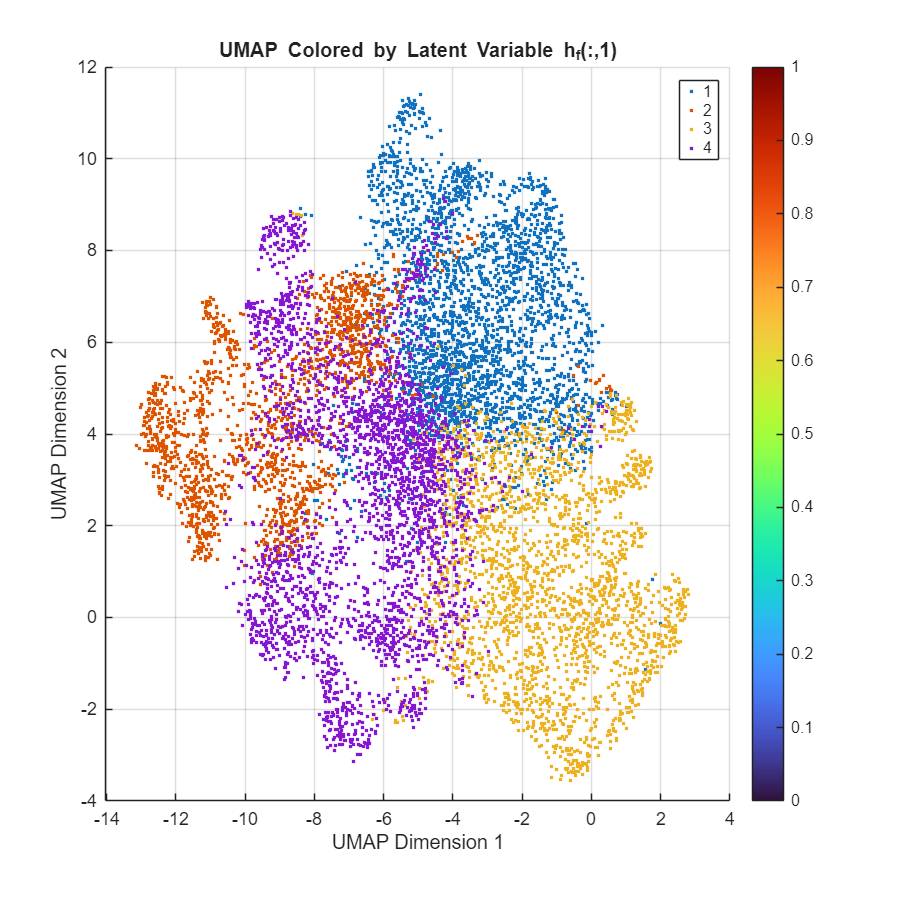


figure('Position',[100,100, 600, 600]);
gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
title({['n=' num2str(curr_n_neighbors)], ['minDist=' num2str(curr_min_dist)]});
xlabel('UMAP Dimension 1');
ylabel('UMAP Dimension 2');
title('UMAP Colored by Latent Variable h_f(:,1)');
colormap turbo;    % You can use 'jet', 'parula', 'hot', etc.
colorbar;
grid on;

PCA MP threshold: keep 14 components.


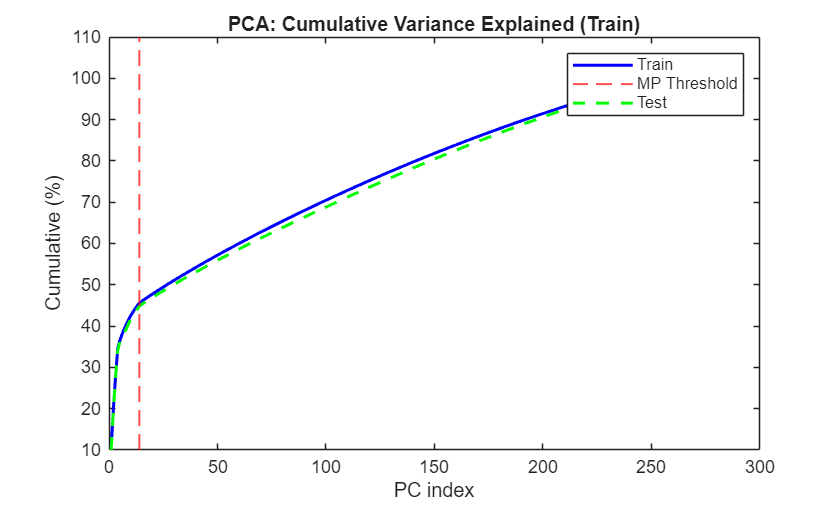

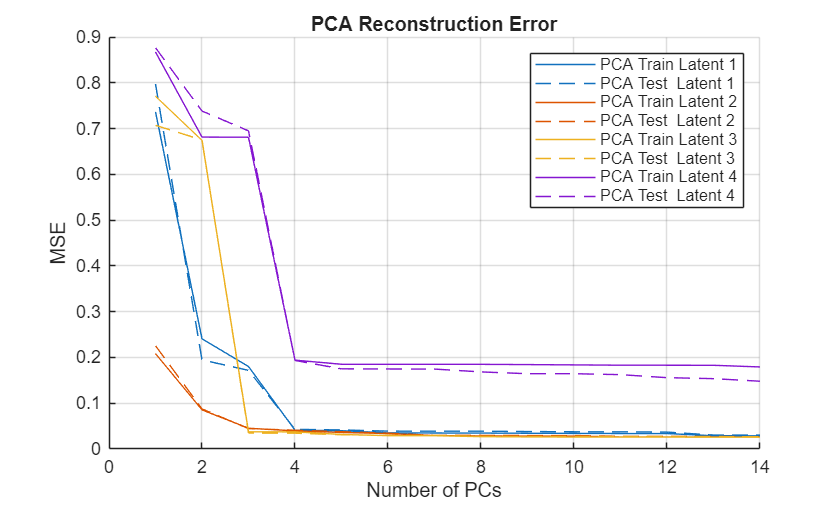

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames

         is not modeling the entire data, only the PCA-reduced data.
Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [14,10000] = 14 channels, 10000 frames/nAfter PCA dimension reduction,
  finding 14 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 51 frames per ICA weight ((196)^2 = 10000 weights, Initial learning rate will be 0.001, block size 47.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -0.3729 to 0.9511
Reducing the data to 14 principal dimensions...
Computing 

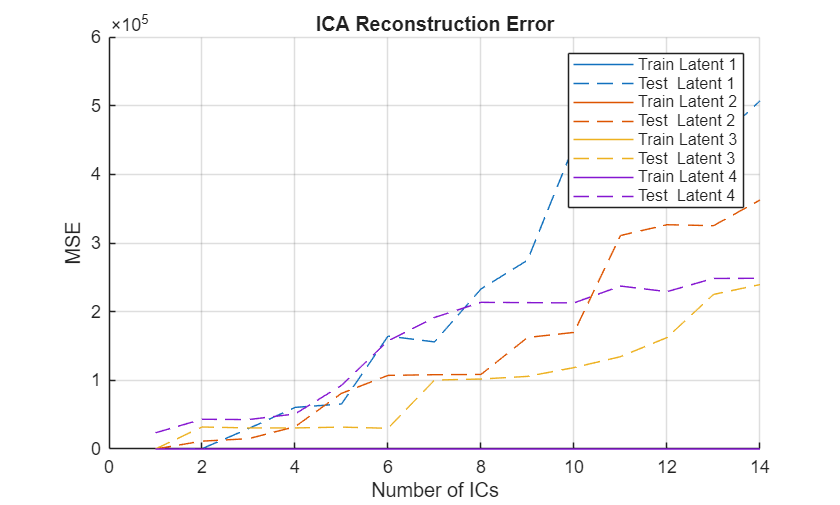

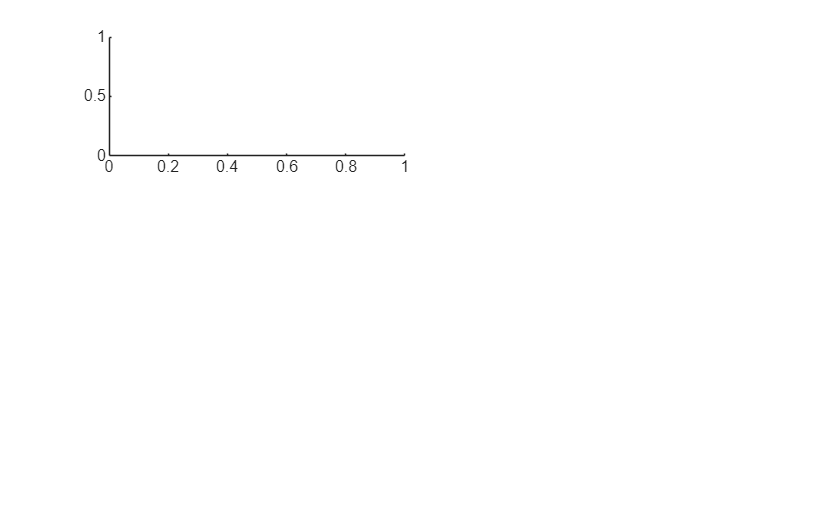

Error using gscatter (line 136)
There must be one value of G for each row of X.

Error in DLV_analysis_main>runUMAPAnalysis (line 163)
        gscatter(emb_train(:,1), emb_train(:,2), cluster_idx_train);
        ^^^^^^^^^^^^^^^^^^^^^

DLV_analysis_main(s_i, param);